# OptMeths_ex5

## Exercise 1

x0 = [0.1; 0.1];
options = optimset('Algorithm', 'active-set', 'Display', 'off');

[x1, fval1, exitflag1, ~, lambda1] = fmincon(@obj_fun1, x0, [], [], [], [], [], [], @nonlcon1, options);

fprintf('Optimal x: [%.4f, %.4f]\n', x1(1), x1(2));

Optimal x: [1.0000, 1.0000]


fprintf('Cost func: %.4f\n', fval1);

Cost func: 2.0000


fprintf('eqnonlin: %.4f\n\n', lambda1.eqnonlin);

eqnonlin: 0.5000



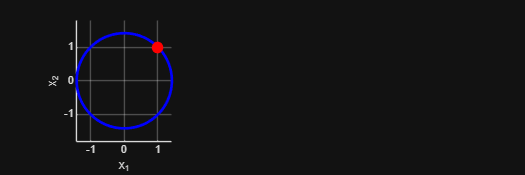


figure('Position', [100, 100, 1200, 400]);
t = linspace(0, 2*pi, 200);

subplot(1,3,1); hold on; grid on; axis equal;
plot(sqrt(2)*cos(t), sqrt(2)*sin(t), 'b', 'LineWidth', 2);
plot(x1(1), x1(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('x_1'); ylabel('x_2');

## Exercise 2

x0_2 = [0.5; 0.5];

lb = [-Inf; 0]; 

[x2, fval2, exitflag2, ~, lambda2] = fmincon(@obj_fun1, x0_2, [], [], [], [], lb, [], @nonlcon2, options);

fprintf('Optimal x: [%.4f, %.4f]\n', x2(1), x2(2));

Optimal x: [-1.4142, 0.0000]


fprintf('Cost func: %.4f\n', fval2);

Cost func: -1.4142


fprintf('ineqnonlin: %.4f\n', lambda2.ineqnonlin);

ineqnonlin: 0.3536


fprintf('x2 >= 0 lower bound: %.4f\n\n', lambda2.lower(2));

x2 >= 0 lower bound: 1.0000



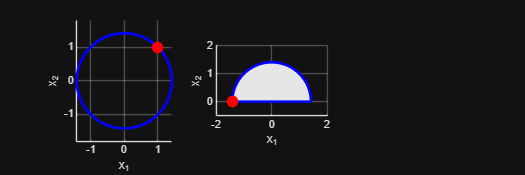


% Wykres Zadanie 2
subplot(1,3,2); hold on; grid on; axis equal;
% Rysowanie obszaru dopuszczalnego (półkole) [cite: 79]
t_semi = linspace(0, pi, 100);
fill([sqrt(2)*cos(t_semi), -sqrt(2)], [sqrt(2)*sin(t_semi), 0], [0.9 0.9 0.9], 'EdgeColor', 'none');
plot(sqrt(2)*cos(t_semi), sqrt(2)*sin(t_semi), 'b', 'LineWidth', 2);
plot([-sqrt(2), sqrt(2)], [0, 0], 'b', 'LineWidth', 2);
plot(x2(1), x2(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('x_1'); ylabel('x_2');
xlim([-2, 2]); ylim([-0.5, 2]);

## Exercise 3

H = [2, 0; 0, 2];
f = [0; 0];

A = [-1, -1];
b = -1;

x0_3 = [0; 0]; 
[x3, fval3, exitflag3, ~, lambda3] = quadprog(H, f, A, b, [], [], [], [], x0_3, options);

fprintf('Optimal x: [%.4f, %.4f]\n', x3(1), x3(2));

Optimal x: [0.5000, 0.5000]


fprintf('Cost func: %.4f\n', fval3);

Cost func: 0.5000


fprintf('ineqlin: %.4f\n\n', lambda3.ineqlin);

ineqlin: 1.0000



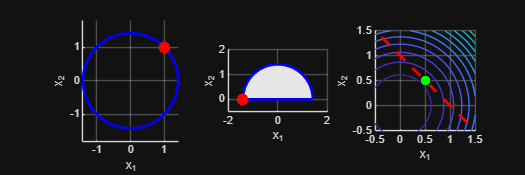


% Wykres Zadanie 3
subplot(1,3,3); hold on; grid on; axis equal;
[X1, X2] = meshgrid(linspace(-1,2,100), linspace(-1,2,100));
Z = X1.^2 + X2.^2;
contour(X1, X2, Z, 20); % Poziomice funkcji celu
% Linia ograniczenia x1 + x2 = 1
x1_line = linspace(-1, 2, 100);
plot(x1_line, 1 - x1_line, 'r--', 'LineWidth', 2);
plot(x3(1), x3(2), 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 8);
xlabel('x_1'); ylabel('x_2');
xlim([-0.5, 1.5]); ylim([-0.5, 1.5]);

## Cost funcs

function f = obj_fun1(x)
f = x(1) + x(2);
end

function [c, ceq] = nonlcon1(x)
c = [];
ceq = x(1)^2 + x(2)^2 - 2;
end

function [c, ceq] = nonlcon2(x)
c = x(1)^2 + x(2)^2 - 2;
ceq = [];
end